# Estimators Project - Magnetic Levitation

**Zeic Beniamin**

## **Lab 1 - Nonlinear Models**

The system for this project consists of an electromagnet and a ball. The control requirement will be to keep the ball in a steady position. 

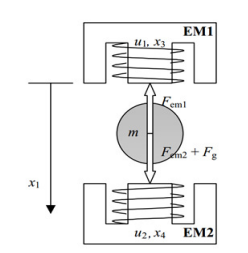

The state space considered will have the following values with physical meaning:

x1 - position of the ball

x2 - velocity of the ball

x3 - intensity of the current passing through coil

The input will be:

u - voltage through the coil

### 1. Simulate the system with initial conditions, no input

The system was simulated with zero initial conditions and zero as input.

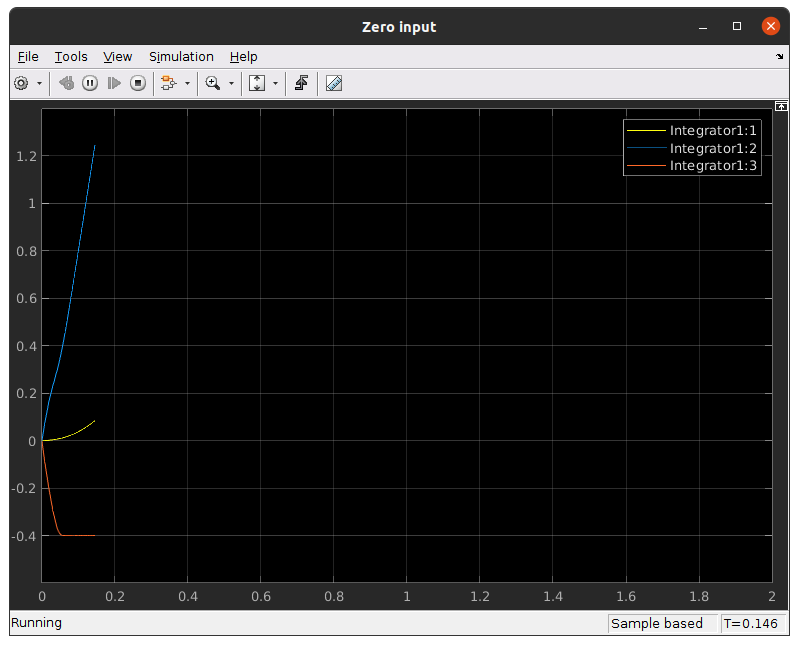

As can be seen, the velocity (blue trace) rapidly tends towards infinity (the ball is basically falling free, since there is no voltage fed through the coil).

### 2. Simulate the system with initial conditions, different non-zero inputs

With a fixed voltage signal of 0.231, the velocity of the ball initially decreases, then it increases towards infinity. This is a sign that the inductance of the coil managed to temporarily counteract the effect that the gravity had over the ball, but since the system is an open-loop one, the ball falled freely afterwards, since the voltage through the coil is uncontrollable, thus the inductance is constant.

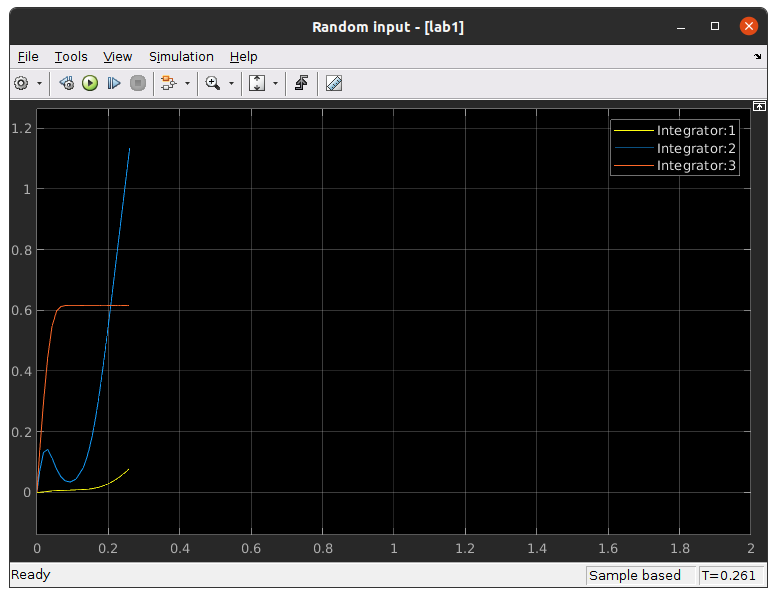

Tests with constant voltages above 0.231 result in a rapidly decreasing ball distance, until it reaches negative values (impossible in a real scenario). Tests with constant voltages under 0.231 result in a rapidly growing ball distance (i.e. the ball is falling freely).

### 3. Simulating with zero initial conditions, non-zero input, distance limited to positive values

Limiting the distance between the ball and the electromagnet to positive values gives the results plotted below:

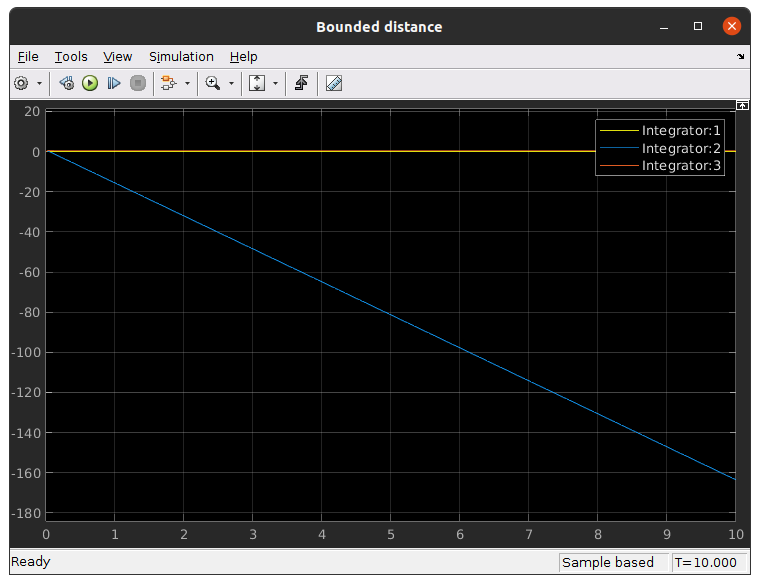

## **Lab 2 - Linear Model, State-Feedback Control, Observer Design**

% System parameters
FemP1 = 0.017521;
FemP2 = 0.0058231;

ci = -0.4;
ki = 4.4;
m = 0.016;
g = 9.81;

fiP1 = 1.4142e-4;
fiP2 = 4.5626e-3;

### **Computing the equilibrium point**

% Set the distance for which to compute the equilibrium point
% Distance between ball an upper coil
x10 = 0.01; % meters
% Initial speed set to zero
x20 = 0;
% Compute x03 from the second equation from equation set (9)
x30 = sqrt((g * 2 * m * FemP2) / (FemP1 * exp(-x10/FemP2)));

% Initial conditions vector
x0 = [x10; x20; x30];
% Use (11) to compute u0
u0 = (x30 - ci)/ki;

### **Calculate the linearization of x2 and x3**

% The linearization formulas below were obtained by linearinzing around the
% point (x10; x20; x30; u0);

% Frequently appearing ratio
fem_ratio = FemP1/(FemP2 * 2 * m);

x2_lin_x1_coeff = - x30^2 * fem_ratio * (-1) * exp(-x10 / FemP2)/FemP2;
x2_lin_x3_coeff = - 2 * x30 * fem_ratio * exp(-x10 / FemP2);

x3_lin_x3_coeff = - fiP2/fiP1 * exp(x10/fiP2);

u_lin_x3_coeff = fiP2/fiP1 * exp(x10/fiP2) * ki;

A = [0                  1       0;
     x2_lin_x1_coeff    0       x2_lin_x3_coeff;
     0                  0       x3_lin_x3_coeff];

B = [0;
     0;
     u_lin_x3_coeff];

### **Controllability matrix & state feedback**

PC = [B, A*B, A^2*B];
rank(PC) % Rank of controlabillity matrix is 3, so we can calculate state feedback gain
% State feedback gain using pole placement
poles = [-20 -41 -200];
K = place(A, B, poles)
% K = place(A, B, [-40, -41, -43]);

**Simulation with dx = [0.001; 0.1; 0], linear model**

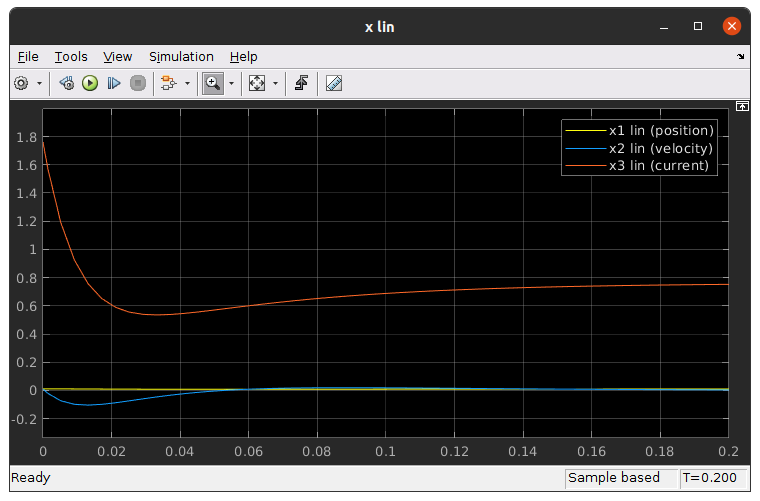

### **Observability matrix **

C = [1 0 0;
     0 0 1;]; % Suppose we have two output states, x1 and x2
PO = [C; C * A; C * A^2];
rank(PO) % Rank of observability matrix = 3, so system is fully observable
% Place the poles
poles = [-40 -101 -200];
L = place(A', C', poles)'

## **Lab 3 - Nonlinear Model, State-Feedback Control, Observer Design**

#### **State Feedback:**

**Simulation with dx = [0.001; 0.1; 0], nonlinear model**

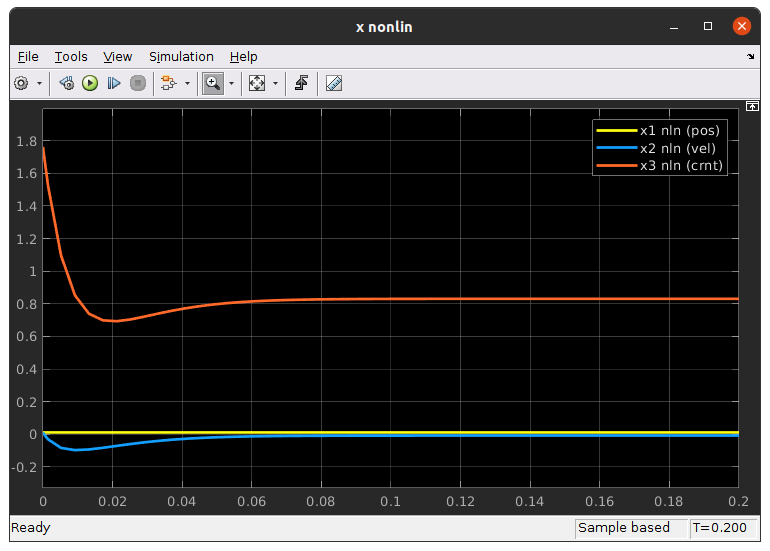

#### Linear Observer:

**Simulation with dx = [0.007; 0; 0], nonlinear model**

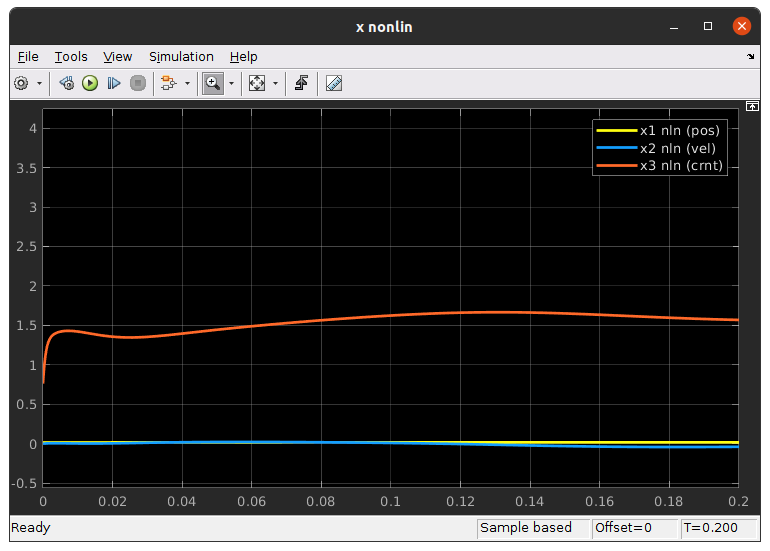

## **Lab 4 & 5 - Discrete-Time Model, Control and Estimation**

#### Discrete state-space matrices Ad and Bd.

clear L K PC PO poles
% Discretization of linear system
Ts = 1e-3;
% Calculate discrete state space
Ad = eye(3) + Ts .* A;
Bd = Ts.*B;
clear A B

#### **Controller computation**

% Controllability matrix
Pcd = [Bd Ad*Bd Ad^2 * Bd];
rank(Pcd); % Controllable if rang == number of states
% Discrete controller
eig(Ad); % Unstable if eigenvalues > 1
poles = [0.82, 0.7, 0.8];
Kd = place(Ad, Bd, poles);

#### Linear model, state feedback

iter = 500;
Dx0 = [0.005; 
        0.01;  
           0];
xls_kn = Dx0;
store = zeros(3, iter);
samples = 1:iter;

for i = 1:iter
    xls_kp = xls_kn;
    store(:, i) = xls_kn + x0;
    xls_kn = Ad * xls_kp + Bd * (-Kd * xls_kp);
end

figure
hold on
plot(samples, store(1,:), 'g');
plot(samples, store(2,:), 'b');
plot(samples, store(3,:), 'r');
% Focus on the region of interest
% ylim([-0.05 0.1])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Discrete Linear State Feedback response (+Dx0)")

#### Nonlinear model, state feedback

clear xls_kn xls_kp store samples iter
iter = 50;
Dx0 = [0; 
       0;  
       0.1];
xns_n = x0 + Dx0;
store = zeros(3, iter);
samples = 1:iter;
for i = 1:iter
    xns_p = xns_n;
    store(:, i) = xns_n;
    xns_n = xns_p + Ts * nonlinear(xns_p, (-Kd * (xns_p - x0) + u0)); % Ad * xns_p + Bd * (-K*x);
end

figure
hold on
plot(samples, store(1,:), 'g');
plot(samples, store(2,:), 'b');
plot(samples, store(3,:), 'r');
% Focus on the region of interest
% ylim([-0.05 0.05])
legend("x1 nln - pos", "x2 nln - vel", "x3 nln - current")
title("Discrete Nonlinear - State Feedback response")

#### Observer computation

% % Observability matrix
poles = [0.82, 0.99, 0.9];
Kd = place(Ad, Bd, poles)
Pd =  [C; C*Ad; C*Ad^2];
poles = [0.87, 0.94, 0.99];
rank(Pd); % Observable if rank == number of states
Ld = place(Ad', C', poles)'

#### Linear model, state feedback + observer

iter = 1000;
samples = 1:iter;
Dx0 = [0.003;
           0;  
           1.3];
Dxh0 = [0;
        0;
        0;];

xlo_n = Dx0;
xlo_hat_n = Dxh0;
store = zeros(3, iter);

for i = 1:iter
    xlo_p = xlo_n;
    xlo_hat_p = xlo_hat_n;

    store(:, i) = xlo_n + x0;

    xlo_n = Ad * xlo_p + Bd * (-Kd * xlo_hat_p);
    err = C * (xlo_p - xlo_hat_p);
    xlo_hat_n = Ad * xlo_hat_p + Bd * (-Kd * xlo_hat_p) + Ld * err;
end

figure
hold on
plot(samples, store(1,:), 'g');
plot(samples, store(2,:), 'b');
plot(samples, store(3,:), 'r');
plot(samples, zeros(iter, 1), 'k');
% Focus on the region of interest
% ylim([-0.1 0.1])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Discrete Linear Observer response")

#### Nonlinear model, state feedback + observer

clear xlo_n xlo_p xlo_hat_n xlo_hat_p err store samples iter
sec = 1;
iter = sec / Ts;
samples = 1:iter;
Dx0 = [0.003;
           0;
           1.3];
Dxh0 = [0;
        0;
        0;];

xno_n = Dx0 + x0;
xno_hat_n = Dxh0;
store = zeros(3,iter);
err_store = zeros(2, iter);

for i = 1:iter
    xno_p = xno_n;
    xno_hat_p = xno_hat_n;

    store(:, i) = xno_n;

    xno_n = xno_p + Ts * nonlinear(xno_p, u0 + (-Kd * xno_hat_p));
    err = C * ((xno_p - x0) - xno_hat_p);
    err_store(:,i) = err;
    xno_hat_n = Ad * xno_hat_p + Bd * (-Kd * xno_hat_p) + Ld * err;%-Kd * xno_hat_p
end


figure
hold on
plot(samples, store(1,:), 'g');
plot(samples, store(2,:), 'b');
plot(samples, store(3,:), 'r');
plot(samples, zeros(iter, 1), 'k');
% Focus on the region of interest
lim = 1;
% ylim([-lim/4 lim])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Discrete Nonlinear Observer response")

## **Lab 6 - Kalman Filter Design**

We can make the following observations out of the Kalman Filter design:

- Too large R (measurement uncertainty) vs Q gain results in  a "smoother" (but not necesarrily better) filter estimation. That's because the inertial prediction takes precedence over the measurement and inertial prediction is by its nature averaging the readings.

- Too small R w.r.t Q results in the filter almost tracking the measurements perfectly, but that rarely happens in the real world, unless we have a really good measurement device.

- Noise in the measurements and filter don't affect the real system as long as the control input is directly fed from the output of the system. When that's changed with the output of the Kalman Estimator, interaction between the estimator and the real system becomes noticeable.

Ad;
Bd;
C;

clear x_p x_hat_prev samples iter Dx0 Dxh0
% How many seconds to run the simulation
sec = 10;
iter = sec/Ts;

% Controls plot limts
lim = 1;
lim_fac = 2;

Dx0 = [ 0.04;
        0;
        1];
Dxh0 = [0;
        -1;
        0;]

Dxh0 =      0
    -1
     0


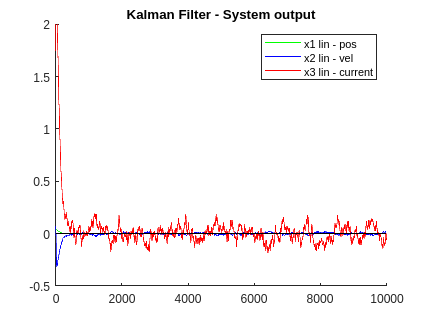


samples = 1:iter;
% Since the model is linearized, having a state vector of zeros means we
% start from the linearisation point.
x = zeros(3,1) + Dx0;
% Suppose we don't have any initial guess about the system, so we start at
% zero
x_hat = zeros(3, 1) + Dxh0;

I = eye(3);

usefile = 1;

if usefile == 1 && length(w_noise) >= iter
    % if exist('w_noise', 'var') == 0 || length(w_noise) < iter
    w_noise = readmatrix("w_noise.txt");
    v_noise = readmatrix("v_noise.txt");
    % end
else
    w_noise = randn(3, iter);
    v_noise = randn(2, iter);

    writematrix(w_noise, "w_noise");
    writematrix(v_noise, "v_noise");
end

alpha1 = 0.5;
alpha2 = 0.1;

R = eye(2) * alpha1;
Q = eye(3) * alpha2;
P = 100 * eye(3);

% Controls the stdev of all noises - use with caution
w_sigma = 1;

% Process noise
w_noise = w_sigma * w_noise;

w_noise(1, :) = w_noise(1, :) * 0.0001; % Position noise
w_noise(2, :) = w_noise(2, :) * 0.001; % Velocity noise
w_noise(3, :) = w_noise(3, :) * 0.001; % Current noise

% Controls the stdev of all noises - use with caution
v_sigma = 1;

v_noise = v_sigma * v_noise;
v_noise(1, :) = v_noise(1, :) * 0.005; % Position measurement noise
v_noise(2, :) = v_noise(2, :) * 0.005; % Current measurement noise

real_state = zeros(3, iter);
predicted_state = zeros(3, iter);
estimated_state = zeros(3, iter);

for i=1:iter
    x_p = x;
    x_hat_p = x_hat;

    % Compute the real system's input
    u_p = -Kd * x_p;
    % Compute the real system's response
    x = Ad * x_p + Bd * u_p + w_noise(:,i);
    % Compute the real system's output
    y = C * x + v_noise(i);
    real_state(:,i) = x;
    
    % This is the observer-like part
    % Predict the system's response
    x_pred = Ad * x_hat_p + Bd * u_p; % x_hat_p
    % Calculate the prediction's uncertainty
    P_pred = Ad * P * Ad' + Q;
    % Gain for the current measurement, based on the measurement's
    % uncertainty
    Kk = P_pred * C' * inv(C * P_pred * C' + R);
    predicted_state(:,i) = x_pred;
    
    % Estimate system state, based on the predicted state and
    % the current measurement (measurement  = y - C*x_pred)
    % (y - C * x_pred)
    x_hat = x_pred + Kk * (y - C * x_pred);
    % Estimate uncertainty of the prediction
    P = (I - Kk * C) * P_pred * (I - Kk * C)' + Kk * R * Kk';
    estimated_state(:, i) = x_hat;
end

figure
hold on
plot(samples, real_state(1,:), 'g');
plot(samples, real_state(2,:), 'b');
plot(samples, real_state(3,:), 'r');
plot(samples, zeros(iter, 1), 'k');
% Focus on the region of interest
ylim([-lim/lim_fac lim * lim_fac])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Kalman Filter - System output")

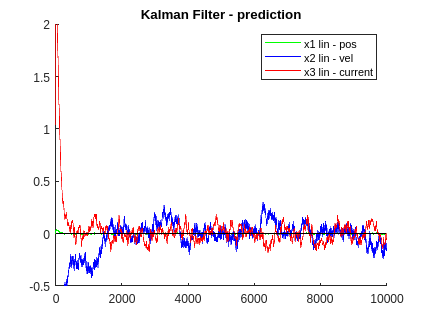


figure
hold on
plot(samples, predicted_state(1,:), 'g');
plot(samples, predicted_state(2,:), 'b');
plot(samples, predicted_state(3,:), 'r');
plot(samples, zeros(iter, 1), 'k');
% Focus on the region of interest
ylim([-lim/lim_fac lim * lim_fac])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Kalman Filter - prediction")

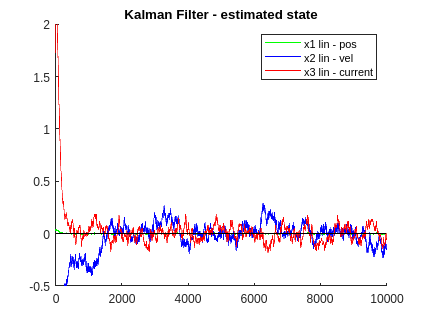


figure
hold on
plot(samples, estimated_state(1,:), 'g');
plot(samples, estimated_state(2,:), 'b');
plot(samples, estimated_state(3,:), 'r');
plot(samples, zeros(iter, 1), 'k');
% Focus on the region of interest
ylim([-lim/lim_fac lim * lim_fac])
legend("x1 lin - pos", "x2 lin - vel", "x3 lin - current")
title("Kalman Filter - estimated state")

% alpha = 0.5;
% beta = 0.01;
% x_dot = [0.01; 0; 0];
% x_est = [0; 0; 0];
% P = 1e3 * eye(3);
% Q = 1e-2 * alpha * eye(3);
% R = 1e3 * beta * eye(1);
% 
% for k = 2:100
%     % Add noisez;r
%     w = 1e-3 * randn(3,1);
%     v = 1e-3 * randn(1,1);
% 
%     u = -Kd * x_est(:, k-1);
% 
%     x_dot(:, k) = Ad * x_dot(:, k-1) + Bd * u + w;
%     y(:, k) = C * x_dot(:, k) + v;
% 
%     x_pred = Ad * x_est(:, k-1) + Bd * u;
%     P_pred = Ad * P * Ad + Q;
%     K = P_pred * C' * inv(C * P_pred * C' + R);
% 
%     x_est(:, k) = x_pred + K * (y(:, k) - C * x_pred);
%     P = (eye(3) - K * C) * P_pred;
% end
% figure
% 
% plot(x_dot')
% legend("x1", "x2", "x3")
% figure
% plot(x_est');
% legend("x1", "x2", "x3")

## **Lab 7 - Extended Kalman Filter Design**

% x_dot = [1e-7; 0; 0] + x0;
% x_hat = x0;
% u = u0;
% alpha = 0.5;
% beta = 0.01;
% P = 1e5 * eye(3);
% Q = 1e-7 * alpha * eye(3);
% R = 1e-7 * beta * eye(1);
% 
% syms x1 x2 x3 u;
% f(x1, x2, x3, u) = [
%     Ts * x2 + x1;
%     Ts * (-(x3^2) * FemP1/(FemP2 * 2 * m) * exp(-x1/FemP2) + g) + x2;
%     Ts * (1/(fiP1/fiP2 * exp(-x1/fiP2) * (ki * u - ci - x3)) + x3);
% ];
% 
% F = jacobian(f, [x1, x2, x3]);
% f_eval = eval(f(x_dot(1,1), x_dot(2,1), x_dot(3,1), u));
% Fk = eval(F(x_hat(1,1), x_hat(2,1), x_hat(3,1), u));
% 
% for k = 2:50
%     w = 1e-7 * randn(3,1);
%     v = 1e-7 * randn(1,1);
% 
%     % k
%     u = u0 - Kd * (x_hat(:, k-1) - x0);
% 
%     f_eval = eval(f(x_dot(1,k-1), x_dot(2,k-1), x_dot(3,k-1), u));
% 
%     x_dot(:, k) = f_eval + w;
%     y(:, k) = C * x_dot(:, k) + v;
% 
%     x_pred = eval(f(x_hat(1,k-1), x_hat(2,k-1), x_hat(3,k-1), u));
% 
%     Fk = eval(F(x_hat(1,k-1), x_hat(2,k-1), x_hat(3,k-1), u));
% 
%     P_pred = Fk(:, 1:3) * P * Fk(:, 1:3)' + Q;
%     K = P_pred * C' *inv(C * P_pred * C' + R);
% 
%     x_hat(:, k) = x_pred + K * (y(:, k) - C * x_pred);
%     P = (eye(3) - K * C) * P_pred;
% end
% 
% figure;
% hold on;
% plot(x_dot(1,:)');
% plot(x_hat(1,:)');

## **Lab 8 - Unknown Input Observer Design**

### Continuous

% E = [1; 0; 0]; % Consider that the posiiton is the affected measurement;
% d = 0.5;
% Ae = [
%     A E;
%     zeros(1,3) 0];
% Be = [
%     B; 
%     0
% ];
% C = [1 1 0];
% Ce = [C 0];
% 
% Poe = [Ce; Ce*Ae; Ce*(Ae^2); Ce*(Ae^3)];
% rank(Poe); % Observable
% eig(Ae); %Unstable
% Le = place(Ae', Ce', [-1, -2, -3, -41])';

### Discrete

% Pode = [Ce; Ce * Ade; Ce * Ade^2; Ce * Ade^3];
% rank(Pode)

### Discrete system

% Ade = eye(4) + Ts .* Ae;
% Bde = Ts .* Be;
% Pode = [Ce; Ce*Ade; Ce*Ade^2];
% rank(Pode) % rank = 3
% Lde = place(transpose(Ade), transpose(Ce), [-0.1, -0.2, -0.3, -.04])';



**Lab 9 - Unknown Input Decoupling Observer and Fault Detection**